# Simscape multibody model og Regbot in balance

initial setup with motor velocity controller this is intended as simulation base for balance control.

close all
clear

## Simulink model name

model='regbot_1mg';

## parameters for REGBOT

motor

RA = 3.3/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.0105; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
%
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## Own REGBOT parameters

% RA = 6.4/2;    % ohm (2 motors)
% JA = 1.3e-6*2; % motor inertia
% LA = 6.6e-3/2; % rotor inductor (2 motors)
% BA = 3e-6*2;   % rotor friction
% Kemf = 0.008; % motor constant
% Km = Kemf;
% % køretøj
% NG = 9.69; % gear
% WR = 0.03; % wheel radius
% Bw = 0.155; % wheel distance
% %
% % model parts used in Simulink
% mmotor = 0.193;   % total mass of motor and gear [kg]
% mframe = 0.32;    % total mass of frame and base print [kg]
% mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
% mpdist =  0.10;   % distance to lit [m]
% % disturbance position (Z)
% pushDist = 0.1; % relative to motor axle [m]

## Controller design parameters

% Wheel velocity to voltage
N_i_vu = 2;
gamma_vu = 90;

% Tilt to velocity controller
N_i_tv = 10;
gamma_tv = 60;
alpha_tv = 0.00001;

% Pre velocity to tilt controller
N_i_vreft = 4;
gamma_vreft = 360+70;
alpha_vreft = 0.3;

% position to pre velocity controller
gamma_xvref = 360+80;
alpha_xvref = 0.3;

## Initial test parameters

x_test = 1;
x_size = 1;
v_size = 1;

## Sample controller values (initialisation)

K_vu = 15;     % Kp
t_i_vu = 0.05;   % Tau_i
Kffvu = 0;     % feed forward constant
startAngle = 10;  % tilt in degrees at time zero
twvlp = 0.005;    % velocity noise low pass filter time constant (recommended)
K_post = 1;
t_i_post = 1;
t_lead_tv = 0;
t_i_tv = 1;
K_tv = 1;
t_i_vreft = 1;
num_lead_vreft = 0;
den_lead_vreft = 1;
K_vreft = 1;
K_xvref = 1;
num_lead_xvref = 0;
den_lead_xvref = 1;

s = tf('s');

## Estimate transfer function for base system using LINEARIZE

Motor volatge to wheel velocity (wv)

load_system(model);
open_system(model);
% define points in model
ios(1) = linio(strcat(model,'/Limit9v'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gvu = minreal(tf(num, den))

Gvu =
 
                  7.023e05 s^3 + 7.023e08 s^2 - 5.083e07 s - 5.083e10
  -----------------------------------------------------------------------------------
  s^6 + 2418 s^5 + 1.317e06 s^4 + 1.872e08 s^3 + 2.371e09 s^2 - 3.032e10 s - 1.881e11
 
Continuous-time transfer function.
Model Properties


## Transfer function from previous exercise

Gvu = tf(796.9,[1 699.2 2761]) 

Gvu =
 
         796.9
  --------------------
  s^2 + 699.2 s + 2761
 
Continuous-time transfer function.
Model Properties


## Bodeplot

pole(Gvu)

ans =  -695.2286
   -3.9714


isstable(Gvu)

ans = logical
   1


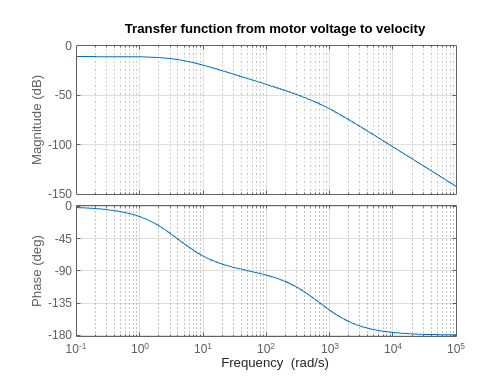

h = figure(100);
bode(Gvu)
grid on
title('Transfer function from motor voltage to velocity')

% saveas(h, 'motor to velocity.png');

## PI-Controller for voltage to velocity

% Design parameters
N_i = 3%N_i_vu;

N_i = 3

gamma_m = 90%gamma_vu;

gamma_m = 90

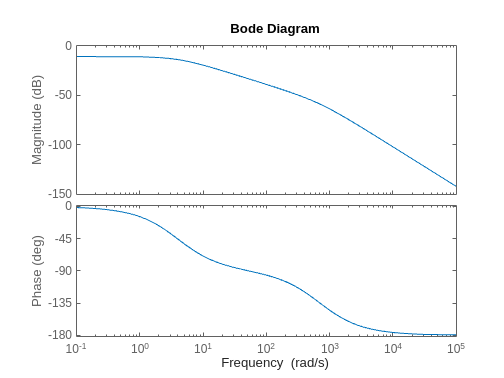


phi_i = rad2deg(-atan(1/N_i));
phi_G = -180+gamma_m-phi_i;

bode(Gvu)

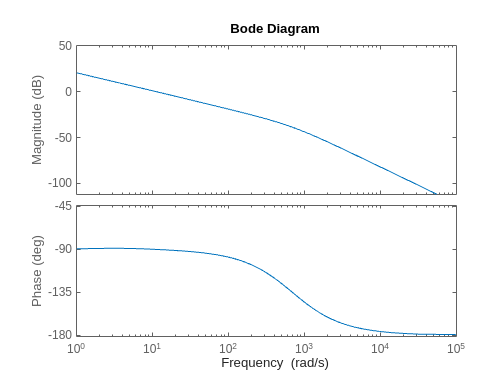


[mag,phase,wout] = bode(Gvu);
omega_c = interp1(squeeze(phase),wout,phi_G);
tau_i = N_i/omega_c;
C_i = tf([tau_i 1],[tau_i 0]);
Kp = 1/abs(freqresp(C_i*Gvu,omega_c*1i));
G_vu_ol = Kp*C_i*Gvu;
G_vu_cl = G_vu_ol/(1+G_vu_ol);
bode(G_vu_ol)

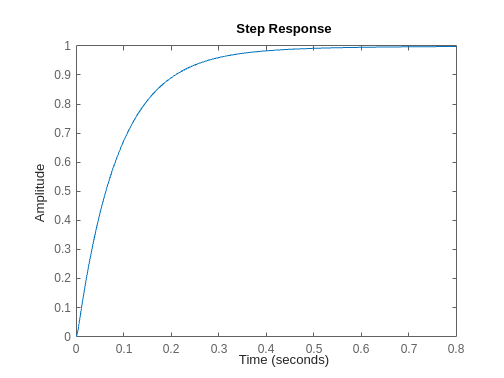

step(G_vu_cl)

## Flush values to model

K_vu = Kp

K_vu = 9.9243

t_i_vu = tau_i

t_i_vu = 0.2652

## **Transfer function from velocity to tilt using linearize**

% define points in model
ios(1) = linio(strcat(model,'/vel_cont'),1,'openinput');
ios(2) = linio(strcat(model, '/tilt_angle'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gtv = minreal(tf(num, den))

Gtv =
 
                 -3.899e05 s^4 - 5.038e08 s^3 - 8.676e10 s^2 - 3.203e11 s - 9.584e08
  --------------------------------------------------------------------------------------------------
  s^7 + 2418 s^6 + 1.317e06 s^5 + 1.942e08 s^4 + 9.367e09 s^3 - 4.544e09 s^2 - 6.945e11 s - 1.902e12
 
Continuous-time transfer function.


h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


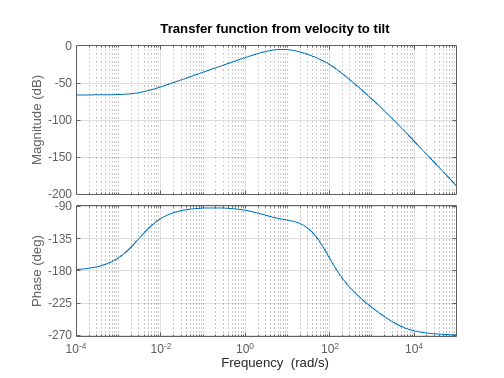

bode(-Gtv)
grid on
title('Transfer function from velocity to tilt')

[mag,phase,wout]=bode(Gtv);

## Post-Integrator

[gpeak,fpeak] = getPeakGain(-Gtv)

gpeak = 0.5820

fpeak = 7.5093

tau_i = 1/fpeak

tau_i = 0.1332

C_pi = -(tau_i*s+1)/(tau_i*s)

C_pi =
 
  -0.1332 s - 1
  -------------
    0.1332 s
 
Continuous-time transfer function.
Model Properties


G_post=Gtv*C_pi

G_post =
 
               5.192e04 s^5 + 6.748e07 s^4 + 1.206e10 s^3 + 1.294e11 s^2 + 3.204e11 s + 9.584e08
  ------------------------------------------------------------------------------------------------------------
  0.1332 s^8 + 322 s^7 + 1.753e05 s^6 + 2.586e07 s^5 + 1.247e09 s^4 - 6.052e08 s^3 - 9.248e10 s^2 - 2.533e11 s
 
Continuous-time transfer function.


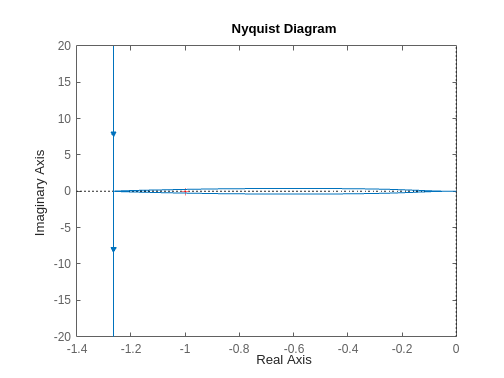

nyquist(G_post)

G_post_cl=minreal(G_post/(1+G_post))

G_post_cl =
 
                 3.899e05 s^5 + 5.067e08 s^4 + 9.054e10 s^3 + 9.718e11 s^2 + 2.406e12 s + 7.197e09
  ---------------------------------------------------------------------------------------------------------------
  s^8 + 2418 s^7 + 1.317e06 s^6 + 1.946e08 s^5 + 9.874e09 s^4 + 8.6e10 s^3 + 2.773e11 s^2 + 5.038e11 s + 7.197e09
 
Continuous-time transfer function.


isstable(G_post_cl)

ans = logical
   1


## Flush values to Simulink

K_post = -1

K_post = -1

t_i_post=tau_i

t_i_post = 0.1332

## Tilt to velocity controller PI-lead

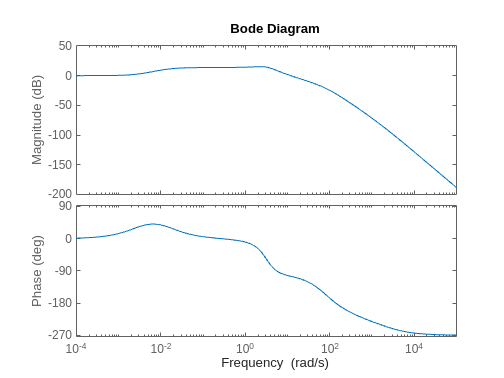

bode(G_post_cl)

% Design parameters
N_i = 8%N_i_tv;

N_i = 8

gamma_m = 65%gamma_tv;

gamma_m = 65

alpha = 0.001%alpha_tv;

alpha = 1.0000e-03



phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_post_cl);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  0.03826 s + 1
  -------------
    0.03826 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
   0.1512 s + 1
  ---------------
  0.0001512 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_post_cl),omega_c);
Kp = 1/mag;

G_tv_ol = minreal(Kp*C_i*C_D*G_post_cl)

G_tv_ol =
 
            1.007e09 s^7 + 1.342e12 s^6 + 2.769e14 s^5 + 1.039e16 s^4 + 1.288e17 s^3 + 6.372e17 s^2 + 1.074e18 s + 3.212e15
  -----------------------------------------------------------------------------------------------------------------------------------
  s^10 + 9030 s^9 + 1.731e07 s^8 + 8.9e09 s^7 + 1.296e12 s^6 + 6.537e13 s^5 + 5.689e14 s^4 + 1.834e15 s^3 + 3.331e15 s^2 + 4.758e13 s
 
Continuous-time transfer function.


G_tv_cl = minreal(G_tv_ol/(1+G_tv_ol))

G_tv_cl =
 
                  1.007e09 s^7 + 1.342e12 s^6 + 2.769e14 s^5 + 1.039e16 s^4 + 1.288e17 s^3 + 6.372e17 s^2 + 1.074e18 s + 3.212e15
  ------------------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 9030 s^9 + 1.731e07 s^8 + 9.907e09 s^7 + 2.638e12 s^6 + 3.422e14 s^5 + 1.096e16 s^4 + 1.306e17 s^3 + 6.405e17 s^2 + 1.074e18 s + 3.212e15
 
Continuous-time transfer function.


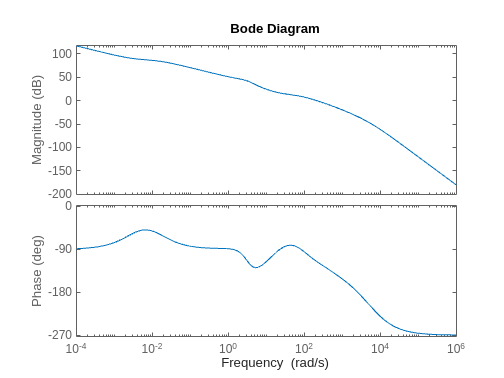


bode(G_tv_ol)

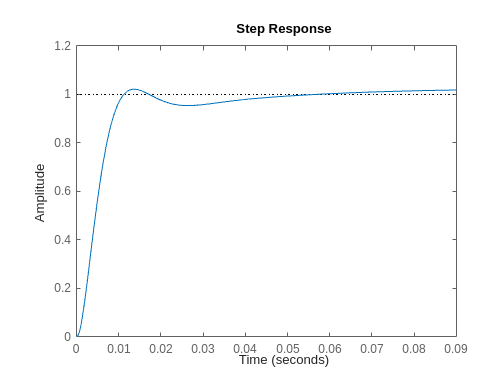

step(G_tv_cl)

## Flush values to simulink

t_lead_tv = tau_D

t_lead_tv = 0.1512

t_i_tv = tau_i

t_i_tv = 0.0383

K_tv = Kp

K_tv = 2.5826

## Transfer function from reference tilt to velocity using linearize

% define points in model
ios(1) = linio(strcat(model,'/tilt_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_vreft = minreal(tf(num, den))

G_vreft =
 
                   -1.8e07 s^6 - 1.867e10 s^5 - 6.78e11 s^4 - 4.478e12 s^3 + 3.585e13 s^2 + 4.219e14 s + 9.642e14
  --------------------------------------------------------------------------------------------------------------------------------
  s^9 + 2418 s^8 + 1.469e06 s^7 + 3.901e08 s^6 + 4.425e10 s^5 + 1.542e12 s^4 + 1.929e13 s^3 + 9.637e13 s^2 + 1.625e14 s + 4.858e11
 
Continuous-time transfer function.


## Reference tilt to velocity controller

isstable(G_vreft)

ans = logical
   1


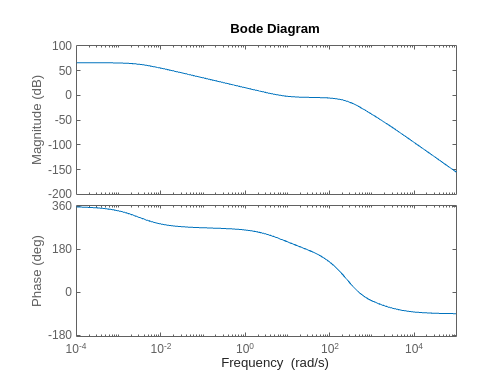

bode(G_vreft)



% Design parameters
N_i = 2%N_i_vreft;

N_i = 2

gamma_m = 60+360%gamma_vreft;

gamma_m = 420

alpha = 0.7 %alpha_vreft;

alpha = 0.7000



phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_vreft);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  1.273 s + 1
  -----------
    1.273 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  0.761 s + 1
  ------------
  0.5327 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_vreft),omega_c);
Kp = 1/mag;

G_vreft_ol = minreal(Kp*C_i*C_D*G_vreft)

G_vreft_ol =
 
              -5.065e06 s^8 - 5.265e09 s^7 - 2.018e11 s^6 - 1.666e12 s^5 + 7.243e12 s^4 + 1.386e14 s^3 + 5.309e14 s^2 + 6.92e14 s + 2.8e14
  -----------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 2420 s^10 + 1.474e06 s^9 + 3.929e08 s^8 + 4.498e10 s^7 + 1.625e12 s^6 + 2.219e13 s^5 + 1.326e14 s^4 + 3.434e14 s^3 + 3.055e14 s^2 + 9.119e11 s
 
Continuous-time transfer function.


G_vreft_cl = minreal(G_vreft_ol/(1+G_vreft_ol))

G_vreft_cl =
 
                  -5.065e06 s^8 - 5.265e09 s^7 - 2.018e11 s^6 - 1.666e12 s^5 + 7.243e12 s^4 + 1.386e14 s^3 + 5.309e14 s^2 + 6.92e14 s + 2.8e14
  ------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 2420 s^10 + 1.474e06 s^9 + 3.878e08 s^8 + 3.971e10 s^7 + 1.423e12 s^6 + 2.052e13 s^5 + 1.398e14 s^4 + 4.82e14 s^3 + 8.365e14 s^2 + 6.93e14 s + 2.8e14
 
Continuous-time transfer function.


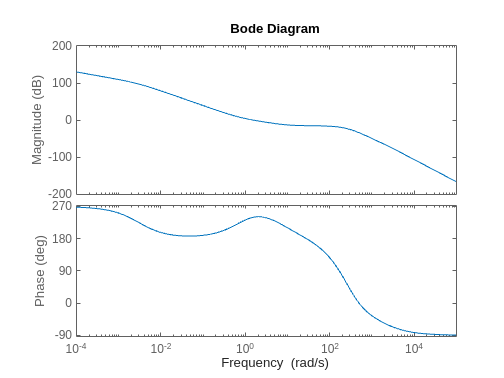


bode(G_vreft_ol)

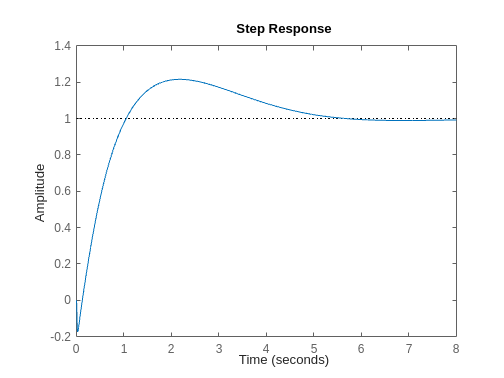

step(G_vreft_cl)

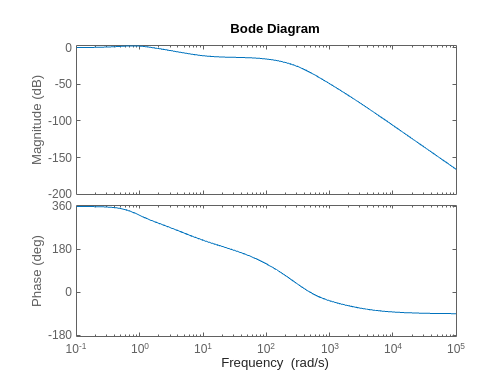

bode(G_vreft_cl)

## Flush values to simulink

t_i_vreft = tau_i

t_i_vreft = 1.2734

[num_lead_vreft,den_lead_vreft] = tfdata(C_D,'v')

num_lead_vreft =     0.7610    1.0000


den_lead_vreft =     0.5327    1.0000


K_vreft = Kp

K_vreft = 0.1970

## Transfer function from vel_pre to x

% define points in model
ios(1) = linio(strcat(model,'/vel_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/x_pos'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_xvref = minreal(tf(num, den))

G_xvref =
 
             -1.773e04 s^9 - 2.199e07 s^8 - 4.415e09 s^7 - 1.517e11 s^6 - 1.292e12 s^5 + 4.478e12 s^4 + 1.056e14 s^3 + 4.726e14 s^2 + 7.992e14 s + 4.539e14
  ---------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 2420 s^11 + 1.474e06 s^10 + 3.948e08 s^9 + 4.672e10 s^8 + 1.459e12 s^7 + 1.997e13 s^6 + 1.362e14 s^5 + 4.825e14 s^4 + 9.009e14 s^3 + 9.015e14 s^2 + 4.539e14 s
 
Continuous-time transfer function.


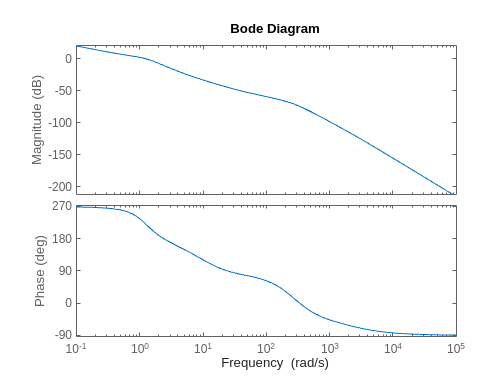

bode(G_xvref)

isstable(G_xvref)

ans = logical
   0


pole(G_xvref)

ans = 1.0e+03 *

   0.0000 + 0.0000i
  -1.6693 + 0.0000i
  -0.2729 + 0.0000i
  -0.2198 + 0.1544i
  -0.2198 - 0.1544i
  -0.0122 + 0.0028i
  -0.0122 - 0.0028i
  -0.0066 + 0.0000i
  -0.0036 + 0.0000i
  -0.0023 + 0.0000i




% Design parameters
gamma_m = 60+360%gamma_xvref;

gamma_m = 420

alpha = 0.5%alpha_xvref;

alpha = 0.5000


phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_m - 180;
[mag,phase,wout] = bode(G_xvref);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));

C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  1.131 s + 1
  ------------
  0.5653 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_D*G_xvref),omega_c);
Kp = 1/mag;

G_xvref_ol = minreal(Kp*C_D*G_xvref)

G_xvref_ol =
 
             -2.528e04 s^10 - 3.138e07 s^9 - 6.324e09 s^8 - 2.219e11 s^7 - 2.034e12 s^6 + 4.756e12 s^5 + 1.562e14 s^4 + 8.071e14 s^3 + 1.736e15 s^2 + 1.655e15 s + 5.726e14
  ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^13 + 2422 s^12 + 1.478e06 s^11 + 3.974e08 s^10 + 4.742e10 s^9 + 1.542e12 s^8 + 2.255e13 s^7 + 1.716e14 s^6 + 7.235e14 s^5 + 1.754e15 s^4 + 2.495e15 s^3 + 2.049e15 s^2 + 8.03e14 s
 
Continuous-time transfer function.


G_xvref_cl = minreal(G_xvref_ol/(1+G_xvref_ol))

G_xvref_cl =
 
                   -2.528e04 s^10 - 3.138e07 s^9 - 6.324e09 s^8 - 2.219e11 s^7 - 2.034e12 s^6 + 4.756e12 s^5 + 1.562e14 s^4 + 8.071e14 s^3 + 1.736e15 s^2 + 1.655e15 s + 5.726e14
  ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^13 + 2422 s^12 + 1.478e06 s^11 + 3.973e08 s^10 + 4.739e10 s^9 + 1.536e12 s^8 + 2.233e13 s^7 + 1.695e14 s^6 + 7.283e14 s^5 + 1.911e15 s^4 + 3.302e15 s^3 + 3.784e15 s^2 + 2.458e15 s + 5.726e14
 
Continuous-time transfer function.


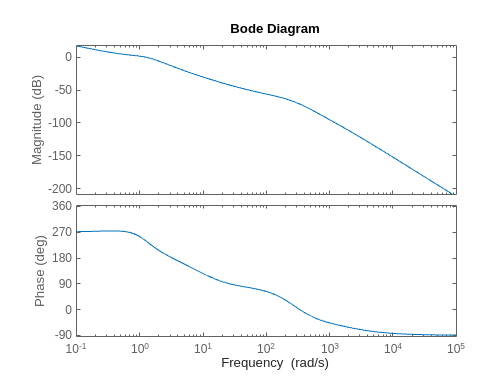


bode(G_xvref_ol)

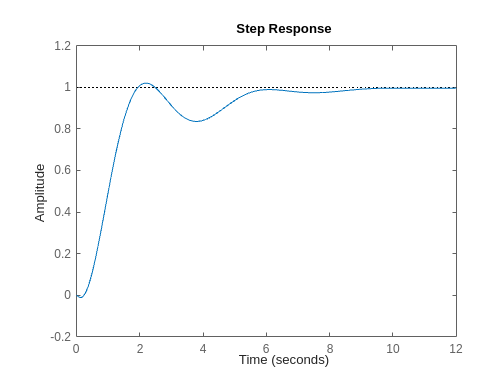

step(G_xvref_cl)

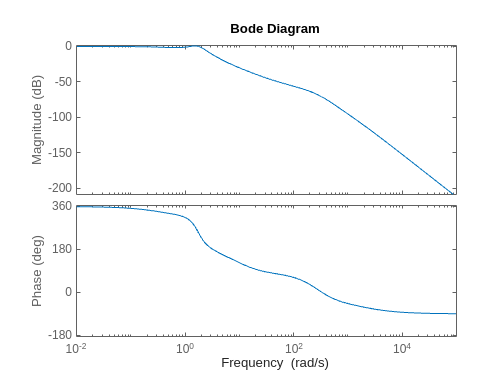

bode(G_xvref_cl)

## Flush values to Simulink

[num_lead_xvref,den_lead_xvref] = tfdata(C_D,'v');
K_xvref = Kp;

## X step test

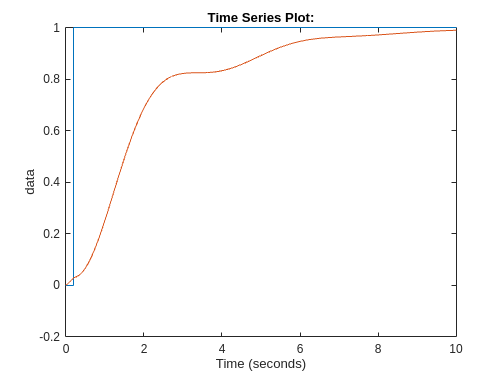

x_test = 1;
x_size = 1;

regsim = sim(model,10);

figure(1);
plot(regsim.ref);
hold on;
plot(regsim.x_pos);
hold off;

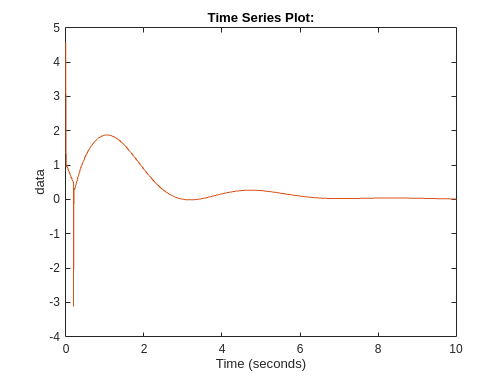


figure(2)
plot(regsim.u)
hold on;
plot(regsim.ulim);
hold off;

## v step size

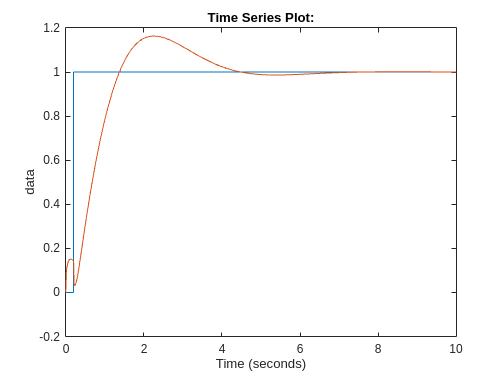

x_test = 0;
v_size = 1;

regsim = sim(model,10);

figure(1);
plot(regsim.vref);
hold on;
plot(regsim.vel);
hold off;

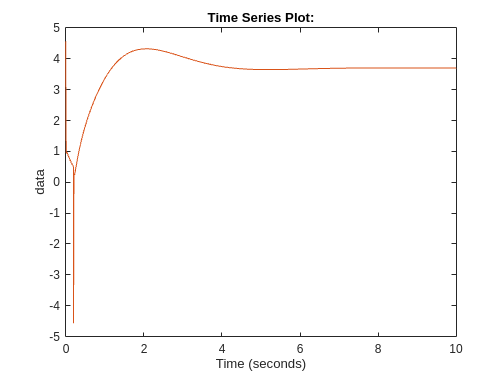


figure(2)
plot(regsim.u)
hold on;
plot(regsim.ulim);
hold off;

## Print controller values

K_vu

K_vu = 9.9243

t_i_vu

t_i_vu = 0.2652

K_post

K_post = -1

t_i_post

t_i_post = 0.1332

t_lead_tv

t_lead_tv = 0.1512

t_i_tv

t_i_tv = 0.0383

K_tv

K_tv = 2.5826

t_i_vreft

t_i_vreft = 1.2734

num_lead_vreft

num_lead_vreft =     0.7610    1.0000


den_lead_vreft

den_lead_vreft =     0.5327    1.0000


K_vreft

K_vreft = 0.1970

K_xvref

K_xvref = 0.7130

num_lead_xvref

num_lead_xvref =     1.1306    1.0000


den_lead_xvref

den_lead_xvref =     0.5653    1.0000
